% cubic polynomial

## Q1

syms tau real
syms a b c d real
syms Dq real
syms qin qfin real
syms vin vfin real
syms T positive real

qn = a*tau^3 + b*tau^2 +c*tau + d 

$$qn = a\,\tau^{3}+b\,\tau^{2}+c\,\tau +d$$

q_tau = qin + Dq*qn

$$q\_tau = \mathrm{qin}+\mathrm{Dq}\,\left(a\,\tau^{3}+b\,\tau^{2}+c\,\tau +d\right)$$


eq_1 = a+b+c==1

$$eq\_1 = a+b+c=1$$

eq_2 = c==vin*T/Dq 

$$eq\_2 = c=\frac{T\,\mathrm{vin}}{\mathrm{Dq}}$$

eq_3 = 3*a+2*b+c == vfin*T/Dq

$$eq\_3 = 3\,a+2\,b+c=\frac{T\,\mathrm{vfin}}{\mathrm{Dq}}$$


s = solve([eq_1, eq_2, eq_3], [a, b, c])

s = struct with fields:
    a: [1×1 sym]
    b: [1×1 sym]
    c: [1×1 sym]


a = simplify(s.a)

$$a = \frac{T\,\mathrm{vfin}-2\,\mathrm{Dq}+T\,\mathrm{vin}}{\mathrm{Dq}}$$

b = simplify(s.b)

$$b = -\frac{T\,\mathrm{vfin}-3\,\mathrm{Dq}+2\,T\,\mathrm{vin}}{\mathrm{Dq}}$$

c = simplify(s.c)

$$c = \frac{T\,\mathrm{vin}}{\mathrm{Dq}}$$


%input
qin = pi

qin = 3.1416

qfin = 1.4805

qfin = 1.4805


vin = 0

vin = 0

vfin = -0.7185

vfin = -0.7185


Dq = qfin-qin;
a = subs(a)

$$a = \frac{404479541533212672\,T}{935112031966857625}-2$$

b = subs(b)

$$b = 3-\frac{404479541533212672\,T}{935112031966857625}$$

c = subs(c)

$$c = 0$$

d = 0

d = 0


fprintf("********************* PLOT WITH T FIXED *************************")

********************* PLOT WITH T FIXED *************************


syms t positive real
q_t = simplify(subs(q_tau, {tau}, {t/T}))

$$q\_t = \mathrm{qin}+\mathrm{Dq}\,\left(d+\frac{a\,t^{3}}{T^{3}}+\frac{b\,t^{2}}{T^{2}}+\frac{c\,t}{T}\right)$$

q_t_dot = diff(q_t, {t})

$$q\_t\_dot = \mathrm{Dq}\,\left(\frac{c}{T}+\frac{3\,a\,t^{2}}{T^{3}}+\frac{2\,b\,t}{T^{2}}\right)$$

q_t_dot_dot = diff(q_t_dot, {t})

$$q\_t\_dot\_dot = \mathrm{Dq}\,\left(\frac{2\,b}{T^{2}}+\frac{6\,a\,t}{T^{3}}\right)$$

q_t_dot_dot_dot = diff(q_t_dot_dot, {t})

$$q\_t\_dot\_dot\_dot = \frac{6\,\mathrm{Dq}\,a}{T^{3}}$$


% plot to undenstad the shape
test_T = 1 % T

test_T = 1

clf
hold on
fprintf("jerk")

jerk

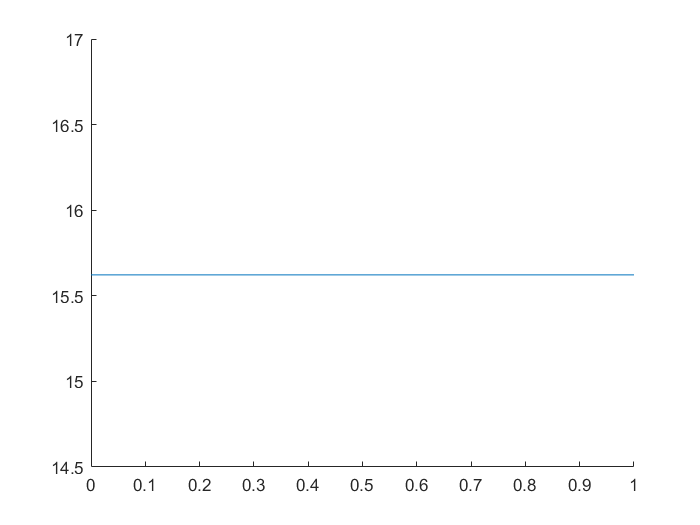

func = subs(q_t_dot_dot_dot);
func = subs(func, {T}, {test_T});
fplot(func, [0, test_T])
hold off


%acceleration
clf
hold on
fprintf("acceleration")

acceleration

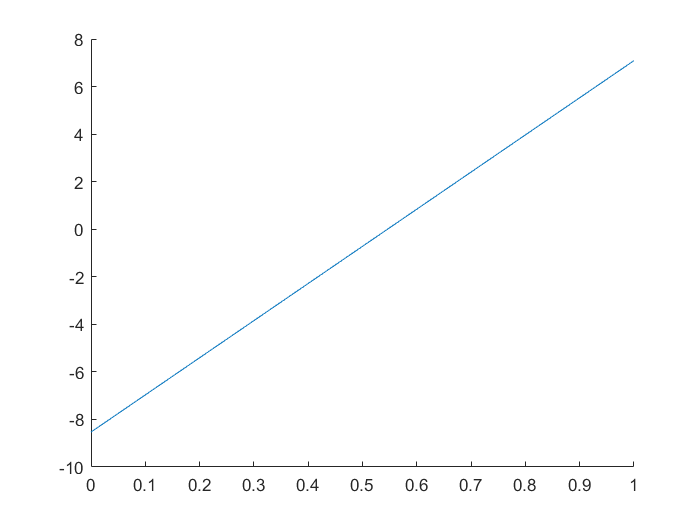

func = subs(q_t_dot_dot);
func = subs(func, {T}, {test_T});
fplot(func, [0, test_T])
hold off 


%velocity
clf
hold on
fprintf("velocity")

velocity

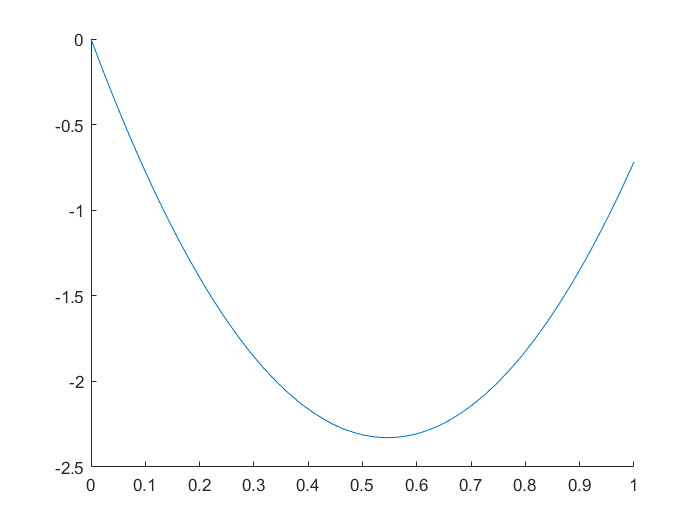

func = subs(q_t_dot);
func = subs(func, {T}, {test_T});
fplot(func, [0, test_T])
hold off 


%position
clf
hold on
fprintf("position")

position

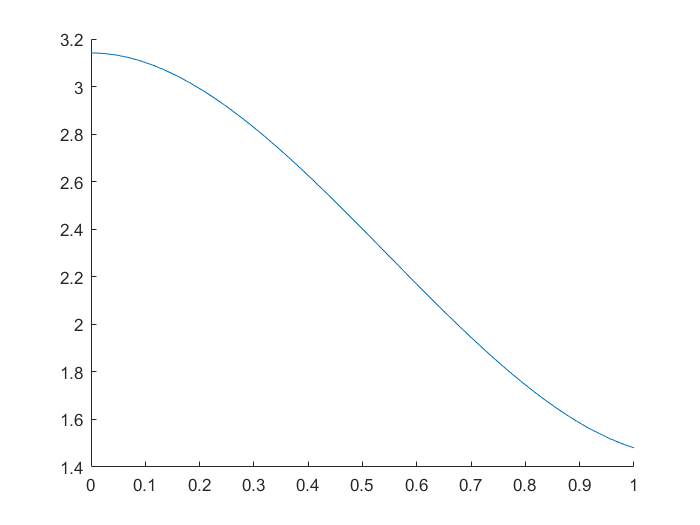

func = subs(q_t);
func = subs(func, {T}, {test_T});
fplot(func, [0, test_T])
hold off 


fprintf("------------------------------------------------------")

------------------------------------------------------



%max values 
%acceleration
func = subs(q_t_dot_dot);
limit_accel = simplify([subs(func, {t}, {0}); subs(func, {t}, {T})]);

%velocities
eq = subs(q_t_dot_dot) == 0;
s = solve(eq, [t], 'ReturnConditions',true);
stat_points_acc = s.t;
func = subs(q_t_dot);
limit_vel = simplify(subs(func, {t}, {stat_points_acc(1)}));


[m, idx] = max(subs(abs(limit_accel), {T}, {1})); %max doesn't work with sym variable
max_acc = simplify(abs(limit_accel(idx)))

$$max\_acc = \frac{\left|404479541533212672\,T-2805336095900572875\right|}{281474976710656000\,T^{2}}$$


[m, idx] = max(subs(abs(limit_vel), {T}, {1})); %max doesn't work with sym variable
max_vel = simplify(abs(limit_vel(idx)))

$$max\_vel = \frac{3\,{\left(134826513844404224\,T-935112031966857625\right)}^{2}}{1125899906842624000\,T\,\left|202239770766606336\,T-935112031966857625\right|}$$


% find minimum T
% NOTE:
%       If the joint planning considers more joints with differemt
%       constraints, then the higher T must be used
%       
%input
v_max = 2

v_max = 2

a_max = 2

a_max = 2


eq_1 = max_acc == a_max

$$eq\_1 = \frac{\left|404479541533212672\,T-2805336095900572875\right|}{281474976710656000\,T^{2}}=2$$

eq_2 = max_vel == v_max

$$eq\_2 = \frac{3\,{\left(134826513844404224\,T-935112031966857625\right)}^{2}}{1125899906842624000\,T\,\left|202239770766606336\,T-935112031966857625\right|}=2$$

T_1 = solve(eq_1, [T])

$$T\_1 = \frac{\sqrt{359748841693559525151}}{8388608000}-\frac{1437}{4000}$$

T_2 = solve(eq_2, [T])

$$T\_2 = \left(\begin{array}{c} \frac{4675560159834288125\,\sqrt{54370}}{356043116434610454528}+\frac{2396692137931056092875}{1424172465738441818112}\\ \frac{5084204117803804907125}{1811663866527259557888}-\frac{4675560159834288125\,\sqrt{25630}}{452915966631814889472}\\ \frac{4675560159834288125\,\sqrt{25630}}{452915966631814889472}+\frac{5084204117803804907125}{1811663866527259557888} \end{array}\right)$$

double(T_2)

ans =     4.7449
    1.1537
    4.4591


%export for final plots
T_min_q1 = max([T_1, T_2])

Error using sym/cat>checkDimensions (line 68)
CAT arguments dimensions not consistent.

Error in sym/cat>catMany (line 33)
[resz, ranges] = checkDimensions(sz,dim);

Error in sym/cat (<a href="m

q_t_ = subs(q_t)
q_t_dot_1 = subs(q_t_dot)
q_t_dot_dot_1 = subs(q_t_dot_dot)
q_t_dot_dot_dot_1 = subs(q_t_dot_dot_dot)